clearvars 
load('combinedTable.mat', 'combinedTable');

folderPath = fullfile(pwd, 'constrainedmodels'); 

% Create folder if it doesn't exist
if ~exist(folderPath, 'dir')
    mkdir(folderPath);
end

lambda = 0.0;

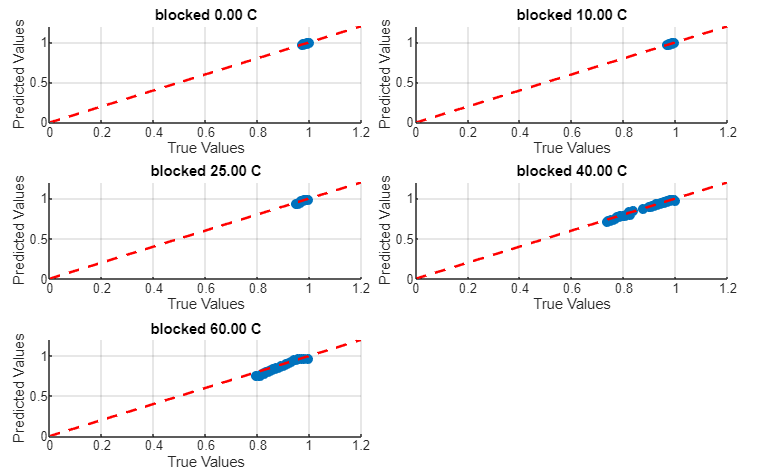

featNames = {'Category','Cch_rate','Cdch_rate','DOD_pct','FEC','SOC_store','T_K','mean_SOC','t_h'};   % raw features
targetCol = 'SOH';  
r2   = @(yPred,yTrue) 1 - sum((yPred(:) - yTrue(:)).^2)/sum((yTrue(:) - mean(yTrue(:))).^2);
unique_TK = unique(combinedTable.T_K);
numRuns = length(unique_TK); 

rmseTrainAll = zeros(numRuns,1);
maeTrainAll  = zeros(numRuns,1);
r2TrainAll   = zeros(numRuns,1);

rmseValAll   = zeros(numRuns,1);
maeValAll    = zeros(numRuns,1);
r2ValAll     = zeros(numRuns,1);

rmseTestAll  = zeros(numRuns,1);
maeTestAll   = zeros(numRuns,1);
r2TestAll    = zeros(numRuns,1);

rng(5) % choose any integer seed    
% Get number of rows
numRows = height(combinedTable);
% Create a random permutation of row indices
shuffledIndices = randperm(numRows);
% Apply the permutation to shuffle the table
shuffledTable = combinedTable(shuffledIndices, :);

X = shuffledTable(:, featNames);
Y = shuffledTable.(targetCol);

numRows = ceil(sqrt(numRuns));
numCols = ceil(numRuns/numRows); 

figureHandle = figure('Position', [100, 100, numRows*1618/2, numRows*1000/2]);  
t = tiledlayout(numRows, numCols, 'Padding','compact','TileSpacing','compact');

for f = 1:length(featNames)
    colData = X.(featNames{f});
    if iscellstr(colData) || isstring(colData) || iscategorical(colData)
        X.(featNames{f}) = double(categorical(colData));
    end
end

X_mat = table2array(X);  % all columns are now numeric

Y_vec = double(Y);   % Ensure numeric target
   
X_mat(isnan(X_mat)) = 0;

for iTK = 1:length(unique_TK)
    
    
    TK = unique_TK(iTK);
   
    % Logical index of rows where column d equals TK
    % Rows where T_K = TK AND 
    % ( (Category=1 AND SOC_store=0.375) 
    % OR (Category=2 AND DOD_pct=80) )

    rowsWithTK = ...
        (X_mat(:, 7) == TK) & ...
        (((X_mat(:, 1) == 1)& (X_mat(:, 6) == 0.5))... %%calender
        | ((X_mat(:, 1) == 2)& (X_mat(:, 4) == 40))); %%cycle


     %%%%
    % Split X_mat into two matrices
    X_test    = X_mat(rowsWithTK, :);   % Rows where d == TK
    X_trainval = X_mat(~rowsWithTK, :);  % Rows where d != TK
    
    % Split Y_vec similarly
    Y_test    = Y_vec(rowsWithTK);
    Y_trainval = Y_vec(~rowsWithTK);

    numTrain = size(X_trainval, 1);
    numVal   = round(0.15 * numTrain);
    numTrain = numTrain - numVal;
    
    X_train = X_trainval(1:numTrain, :);
    Y_train = Y_trainval(1:numTrain);

    X_val = X_trainval(numTrain+1:end, :);
    Y_val = Y_trainval(numTrain+1:end);
    
     mu = mean(X_mat);
    sigma = std(X_mat);
    X_train = (X_train - mu) ./ sigma;
    X_val   = (X_val - mu) ./ sigma;
    X_test  = (X_test - mu) ./ sigma;

layers = [
    featureInputLayer(9,'Name','in')

    fullyConnectedLayer(64,'Name','fc1')
    reluLayer('Name','relu1')

    fullyConnectedLayer(32,'Name','fc2')
    reluLayer('Name','relu2')

    fullyConnectedLayer(1,'Name','out')
    sigmoidLayer('Name','sigOut')
];

miniB = 32;
opts = trainingOptions('adam', ...
    'InitialLearnRate',0.001498, ...
    'MaxEpochs',250, ...
    'MiniBatchSize',miniB, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{X_val,Y_val}, ...
    'ValidationFrequency',max(1,floor(size(X_train,1)/miniB)), ...
    'ValidationPatience',72, ...
    'L2Regularization',0.000001, ...
    'Verbose',false, ...
    'GradientThresholdMethod','l2norm' ...
    ,'GradientThreshold',1, ...
    'LearnRateSchedule','piecewise' , ...
    'LearnRateDropPeriod',100, ...
    'LearnRateDropFactor',0.84);
    % Train
    switch true
        case lambda ~= 0
        net = dlnetwork(layers);
        [net, ~, ~] = trainNetworkCustom(net,...
        X_train, Y_train, ...
        X_val, Y_val, ...
        opts, lambda);
        case lambda == 0
             layers = [layers; regressionLayer('Name','reg')];
             net = trainNetwork(X_train, Y_train, layers, opts);
    end
  % Get predictions (no transposes needed)
    Y_train_pred = predict(net, X_train);
    Y_val_pred   = predict(net, X_val);
    Y_test_pred  = predict(net, X_test);
    
    % Ensure column vectors
    Y_train_pred = Y_train_pred(:);
    Y_val_pred   = Y_val_pred(:);
    Y_test_pred  = Y_test_pred(:);
    
    % --- Training metrics ---
    rmseTrainAll(iTK) = sqrt(mean((Y_train - Y_train_pred).^2));
    maeTrainAll(iTK)  = mean(abs(Y_train - Y_train_pred));
    r2TrainAll(iTK)   = r2(Y_train_pred,Y_train);

    % --- Validation metrics ---
    rmseValAll(iTK) = sqrt(mean((Y_val - Y_val_pred).^2));
    maeValAll(iTK)  = mean(abs(Y_val - Y_val_pred));
    r2ValAll(iTK)   = r2(Y_val_pred,Y_val);
    % --- Test metrics ---
    rmseTestAll(iTK) = sqrt(mean((Y_test - Y_test_pred).^2));
    maeTestAll(iTK)  = mean(abs(Y_test - Y_test_pred));
    r2TestAll(iTK)   = r2(Y_test_pred,Y_test);
 
    modelname = sprintf('blocked_%.2f_Seed_%d_RMSE_%.4f_MAE_%.4f_R2_%.4f_lambda_%.4f.mat',...
        unique_TK(iTK),5,rmseTestAll(iTK),maeTestAll(iTK),r2TestAll(iTK),lambda);
 
    save(fullfile(folderPath, modelname) , 'net');

    nexttile
    scatter(Y_test, Y_test_pred, 'filled');
    hold on;
    plot([0, 1.2], [0, 1.2], 'r--', 'LineWidth', 1.5);
    hold off;
    xlabel('True Values');
    ylabel('Predicted Values');
    title(sprintf('blocked %.2f C', unique_TK(iTK)-273.15));
    grid on;
    
end 

figName = fullfile(folderPath, 'AllRuns_PredVsTrue.png');
exportgraphics(figureHandle, figName, 'Resolution', 300);


RunNames = string(unique_TK');

metricsTable = table(RunNames', ...
rmseTrainAll, maeTrainAll, r2TrainAll, ...
rmseValAll, maeValAll, r2ValAll, ...
rmseTestAll, maeTestAll, r2TestAll, ...
'VariableNames', {'Run', ...
'RMSE_Train','MAE_Train','R2_Train', ...
'RMSE_Val','MAE_Val','R2_Val', ...
'RMSE_Test','MAE_Test','R2_Test'});

meanRow = {NaN, mean(rmseTrainAll), mean(maeTrainAll), mean(r2TrainAll), ...
               mean(rmseValAll), mean(maeValAll), mean(r2ValAll), ...
               mean(rmseTestAll), mean(maeTestAll), mean(r2TestAll)};

stdRow  = {NaN, std(rmseTrainAll), std(maeTrainAll), std(r2TrainAll), ...
               std(rmseValAll), std(maeValAll), std(r2ValAll), ...
               std(rmseTestAll), std(maeTestAll), std(r2TestAll)};

% Append mean and std as extra rows
metricsTable = [metricsTable; ...
    cell2table(meanRow, 'VariableNames', metricsTable.Properties.VariableNames); ...
    cell2table(stdRow,  'VariableNames', metricsTable.Properties.VariableNames)];

% Optional: label these rows
metricsTable.Run = string(metricsTable.Run);  % convert numeric to string
metricsTable.Run(end-1:end) = ["Mean"; "Std"];% Display the table
disp(metricsTable);

      Run       RMSE_Train    MAE_Train      R2_Train      RMSE_Val      MAE_Val        R2_Val      RMSE_Test    MAE_Test     R2_Test
    ________    __________    __________    __________    __________    __________    __________    _________    _________    _______

    "273.15"     0.0060444     0.0041221       0.99412     0.0053149     0.0039965       0.99569    0.0017953    0.0014341    0.93803
    "283.15"      0.005351     0.0037319       0.99542     0.0048155     0.0035128       0.99645    0.0017188    0.0013127    0.95729
    "298.15"     0.0050271     0.0035318       0.99598     0.0046585     0.0035469       0.99672     0.011315    0.0082587 


% Construct filename
csvName = fullfile(folderPath, 'Metrics_AllRuns.csv');

% Export table to CSV
writetable(metricsTable, csvName);

disp(['Metrics table saved as: ', csvName]);

Metrics table saved as: D:\Projects\Battery_and_hydrogen_ESS_modeling_using_physcis_based_ML_Modeling\BESS\constrainedmodels\Metrics_AllRuns.csv
